clear
clc

opts = optimoptions('fmincon','SpecifyObjectiveGradient',false,'Display','iter');

x0 = [15.7329	0.4169	0.0333	-5.3921	9.8840	-5.4486] + 5;
%x0 = [10 8/3 28 1 1 1];

tic
[xv,Rv] = fmincon(@(x) objective(x),x0,[],[],[],[],[0 0 0 -10 -10 -10],[30 30 30 10 10 10],[],opts)

Initial point X0 is not between bounds LB and UB; 
FMINCON shifted X0 to strictly satisfy the bounds.

                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       7    5.996340e+01    0.000e+00    2.281e+01
    1      14    3.957536e-06    0.000e+00    1.486e+00    5.291e+00
    2      21    1.487831e-08    0.000e+00    8.648e-02    4.755e-01
    3      28    5.367112e-09    0.000e+00    1.409e-02    5.017e-03
    4      35    8.561968e-09    0.000e+00    1.108e-02    1.997e-02
    5      42    8.973422e-09    0.000e+00    6.415e-03    5.632e-02
    6      49    2.255821e-07    0.000e+00    1.741e-02    1.363e-01
    7      56    8.514349e-04    0.000e+00    2.713e+03    6.596e-01
    8      64    1.471388e-07    0.000e+00    7.715e+00    1.762e+00
    9      72    4.868064e-04    0.000e+00    5.408e+00    1.476e+00
   10      92    4.839068e-04    0.000e+00    9.218e-03    6.253e-03
   11     102

xv =    20.7801    1.7223    0.8039   -0.2280    6.9286   -0.5521


Rv = 7.2982e-05

Optimizer_time = toc

Optimizer_time = 0.8975

A = AutoDiff([xv(1) xv(2) xv(3) xv(4) xv(5) xv(6)]);

tic
[tf, yf] = ODE.rkf45(@(t,y) ODE.test.LorenzRHS(t,y,A(1),A(2),A(3)), [A(4);A(5);A(6)], 0, 10, 0.01,  1e-9, A);
Sensitivities_time = toc

Sensitivities_time = 2.5726


L = sum((yf{end} - [0;0;0]).^2);

dL = full(getderivs(L))

dL =     0.0001    0.0006    0.0026   -0.0001   -0.0003   -0.0000


L = getvalue(L)

L = 1.3187e-04

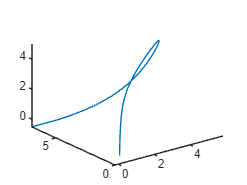


for i = 1:length(tf)
    yfv(:,i) = getvalue(yf{i});
    dyfv(:,:,i) = full(getderivs(yf{i}));
end

figure
plot3(yfv(1,:),yfv(2,:),yfv(3,:))

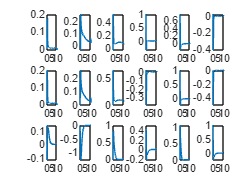


[nx,ny,~] = size(dyfv);

figure
k=0;
for i = 1:nx
    for j = 1:ny
        k=k+1;
        subplot(nx,ny,k)
        plot(tf,squeeze(dyfv(i,j,:)))
    end
end

function [L] = objective(x)

A = [x(1) x(2) x(3) x(4) x(5) x(6)];

[~, yf] = ODE.rkf45(@(t,y) ODE.test.LorenzRHS(t,y,A(1),A(2),A(3)), [A(4);A(5);A(6)], 0, 10, 0.01,  1e-4);

L = sum((yf{end} - [0;0;0]).^2);

end